# ME5554/AOE5754/ECE5754 - Midterm Exam - Fall 2023

Honor Statement:  I pledge that I have neither given nor received unauthorized aid on this exam:

Name: Samuel Kramer

% --Setup
    clear; clc; format compact; close all;

## Problem 1  [10 pts]

Show that **Dynamic System 1** and **Dynamic System 2** are mathematically equivalent.

You may use the Symbolic Toolbox.  You may use the Control System Toolbox.  You may use the LiveScript equation editor.  You may use basic Matlab functions.  You MUST show the steps and display all intermediate and final results.  If you have the correct answer, but do not show how you got that answer, points will be taken off.

**Dynamic System 1: ** $\ddddot{y} +12\dddot{y} +71\ddot{y} +118\dot{y} +98y=5\left(\ddot{u} +2\dot{u} +2u\right)$


$$\ddddot{y} + 12\dddot{y} + 71\ddot{y} + 98y = 5\ddot{u} + 10\dot{u} + 10u$$


$L${ $\ddddot{y} + 12\dddot{y} + 71\ddot{y} + 98y = 5\ddot{u} + 10\dot{u} + 10u$}


$$s^4y(s) + 12s^3y(s)+ 71s^2y(s) + 98y(s) = 5s^2u(s) + 10su(s) + 10u(s)$$



$$(s^4 + 12s^3 + 71s^2 + 98) Y = (5s^2 + 10s + 10) U$$


$\frac{Y}{U} = \frac{5s^2 + 10s + 10}{s^4 + 12s^3 +71s^2 + 98}$   <-- Transfer Function H(s)

% --Setup
    clear; clc; format compact; close all;

% --Define TF equations
    num = [1 2 2];
    denom = [1 12 71 0 98];
    roots_num = roots(num)

roots_num =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


    roots_denom = roots(denom)

roots_denom =   -6.1142 + 5.9209i
  -6.1142 - 5.9209i
   0.1142 + 1.1575i
   0.1142 - 1.1575i


**Dynamic System 2:**  $\dot{\mathbf{x}} =\mathbf{A}\;\mathbf{x}+\mathbf{B}\;u$, and $y=\mathbf{C}\;\mathbf{x}+\mathbf{D}\;u$, where:

% --Define the Sections
    A = [2  -3  1; 
        -10 11 -5; 
        -46 62 -23];
    B = [0; 1; 3];
    C = [2 -3 1];
    D = [0];

% --Convert to a TF-equation
    [num, denom] = ss2tf(A,B,C,D);
    Hs = tf(num,denom)

Hs =
 
          5 s - 3.14e-15
  -------------------------------
  s^3 + 10 s^2 + 49 s - 4.294e-14
 
Continuous-time transfer function.
Model Properties


## Problem 2   [10 pts]

Given a homogeneous state-space dynamic system defined by:  $\dot{\mathbf{x}} =\mathbf{A}\;\mathbf{x}$, where:

% --Setup
    clear; clc; format compact; close all;
   
% --Problem Statement
    A = [-3 -1 -1; 
          2 -6  2; 
         -3  3 -5];

You may use the Symbolic Toolbox.  You may use the Control System Toolbox.  You may use the LiveScript equation editor.  You may use basic Matlab functions.  You MUST show the steps and display all intermediate and final results.  If you have the correct answer, but do not show how you got that answer, points will be taken off.

a) [4 pts]  Determine the **State Transition Matrix **using the **Method of Diagonalization**.

% --Findin STM using diagonalization
    syms e t
    [eig_vectors, eig_vals] = eig(A)

eig_vectors =    -0.0000    0.7071    0.7071
    0.7071   -0.0000    0.7071
   -0.7071   -0.7071    0.0000


eig_vals =    -8.0000         0         0
         0   -2.0000         0
         0         0   -4.0000


    inv_eig_vectors = inv(eig_vectors)

inv_eig_vectors =    -0.7071    0.7071   -0.7071
    0.7071   -0.7071   -0.7071
    0.7071    0.7071    0.7071


    eAt = [e^(-8*t) 0 0;
            0 e^(-2*t) 0;
            0 0 e^(-4*t)];
    eAt = eig_vectors * eAt * inv_eig_vectors;
    eAt = collect(simplify(eAt),t)

$$eAt = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{5}+\sigma_{3}+\sigma_{2} & \sigma_{2}-\sigma_{3}-\sigma_{5} & \sigma_{5}-\sigma_{3}+\sigma_{2}\\ \sigma_{2}-\sigma_{6}-\sigma_{1} & \sigma_{6}+\sigma_{2}+\sigma_{1} & \sigma_{6}+\sigma_{2}-\sigma_{1}\\ \sigma_{4}-\sigma_{3}+\sigma_{1} & \sigma_{4}+\sigma_{3}-\sigma_{1} & \sigma_{4}+\sigma_{3}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{2\,e^{8\,t}}\\ \sigma_{2}=\frac{1}{2\,e^{4\,t}}\\ \sigma_{3}=\frac{1}{2\,e^{2\,t}}\\ \sigma_{4}=\frac{3530660105870583\,\sqrt{2}}{5070602400912917605986812821504\,e^{4\,t}}\\ \sigma_{5}=\frac{1128822109354423\,\sqrt{2}}{5070602400912917605986812821504\,e^{8\,t}}\\ \sigma_{6}=\frac{3378478194420007\,\sqrt{2}}{10141204801825835211973625643008\,e^{2\,t}} \end{array}$$

% --Using laplace to confirm
    syms s
    B = s*eye(3) - A;
    C = inv(B);
    eAt = ilaplace(C)

$$eAt = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2}+\frac{{\mathrm{e}}^{-4\,t}}{2} & \frac{{\mathrm{e}}^{-4\,t}}{2}-\sigma_{2} & \frac{{\mathrm{e}}^{-4\,t}}{2}-\sigma_{2}\\ \frac{{\mathrm{e}}^{-4\,t}}{2}-\sigma_{1} & \frac{{\mathrm{e}}^{-4\,t}}{2}+\sigma_{1} & \frac{{\mathrm{e}}^{-4\,t}}{2}-\sigma_{1}\\ \sigma_{1}-\sigma_{2} & \sigma_{2}-\sigma_{1} & \sigma_{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{-8\,t}}{2}\\ \sigma_{2}=\frac{{\mathrm{e}}^{-2\,t}}{2} \end{array}$$

Both are similar, however there are additional terms in the method of diagonalization being $\sigma_4$ through $\sigma_6$

b)  [2 pts]  Solve for the **initial value response** due the following initial conditions.

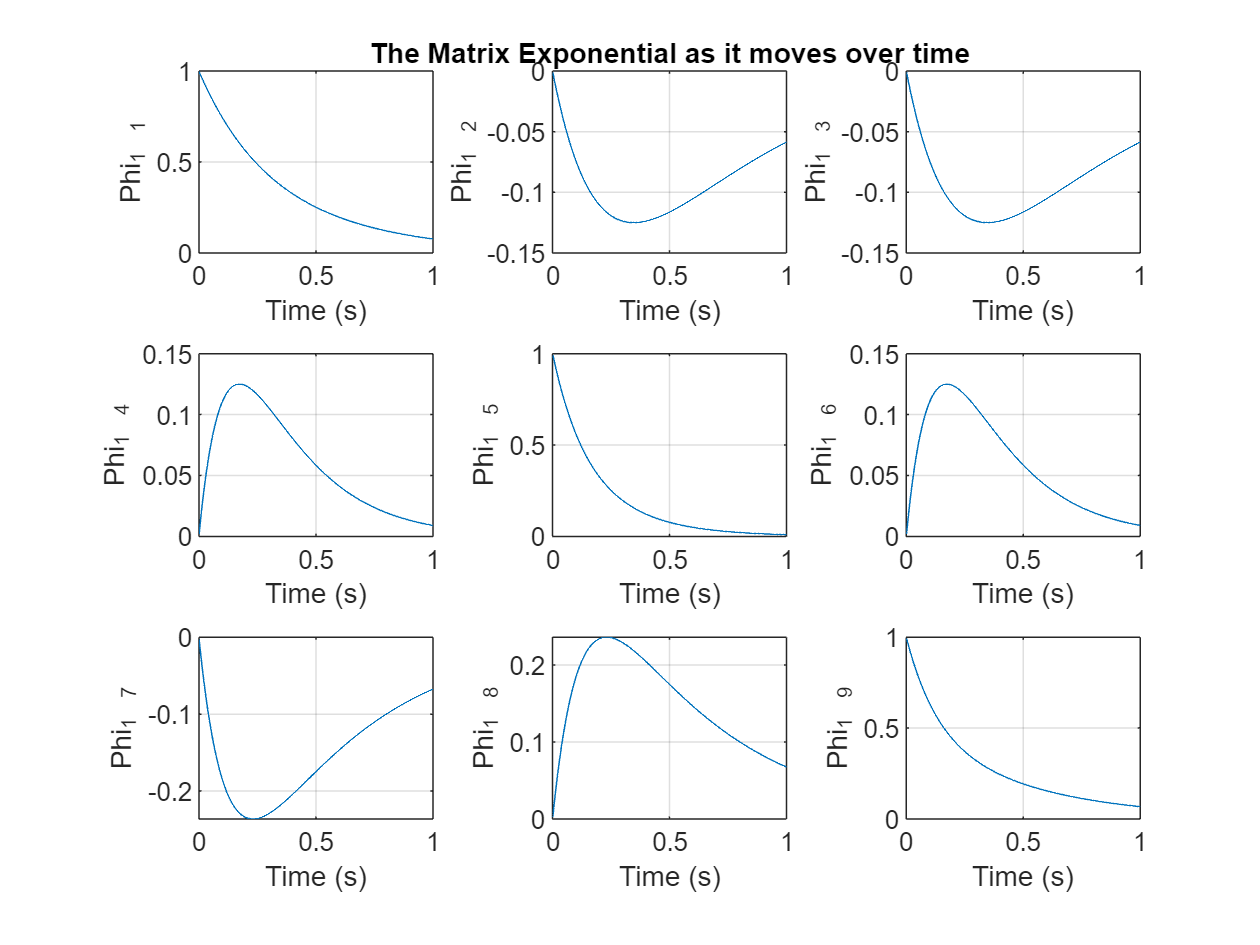

% --Problem statement
    X0b = [0; 1; -1];

    fs = 1000;
    maxt = 1;
    t = 0:1/fs:maxt;
    phi = zeros(3,3,fs);
    for i = 1:(fs*maxt) + 1
        phi(:,:,i) = expm(A*t(i));
    end

% --Plot solutions
    figure(1)
    for i = 1:3
        figure(1)
        subplot(3,3,1*i)
        x = squeeze(phi(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 3)
        x = squeeze(phi(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i+3);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 6)
        x = squeeze(phi(3,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i+6);
            ylabel(label)
            xlabel('Time (s)')
            grid on
    end
    figure(1)
    subplot(3,3,2)
    title("The Matrix Exponential as it moves over time")

We can now follow the Initial Value Response by using the following equation $x(t) = e^{At}(t,t_0)x(t_0)$ and if $e^{At}$ is [3x3] and $x(t_0)$ is [3x1] then we will get the three states as they evolve over time in a diagonal representation.

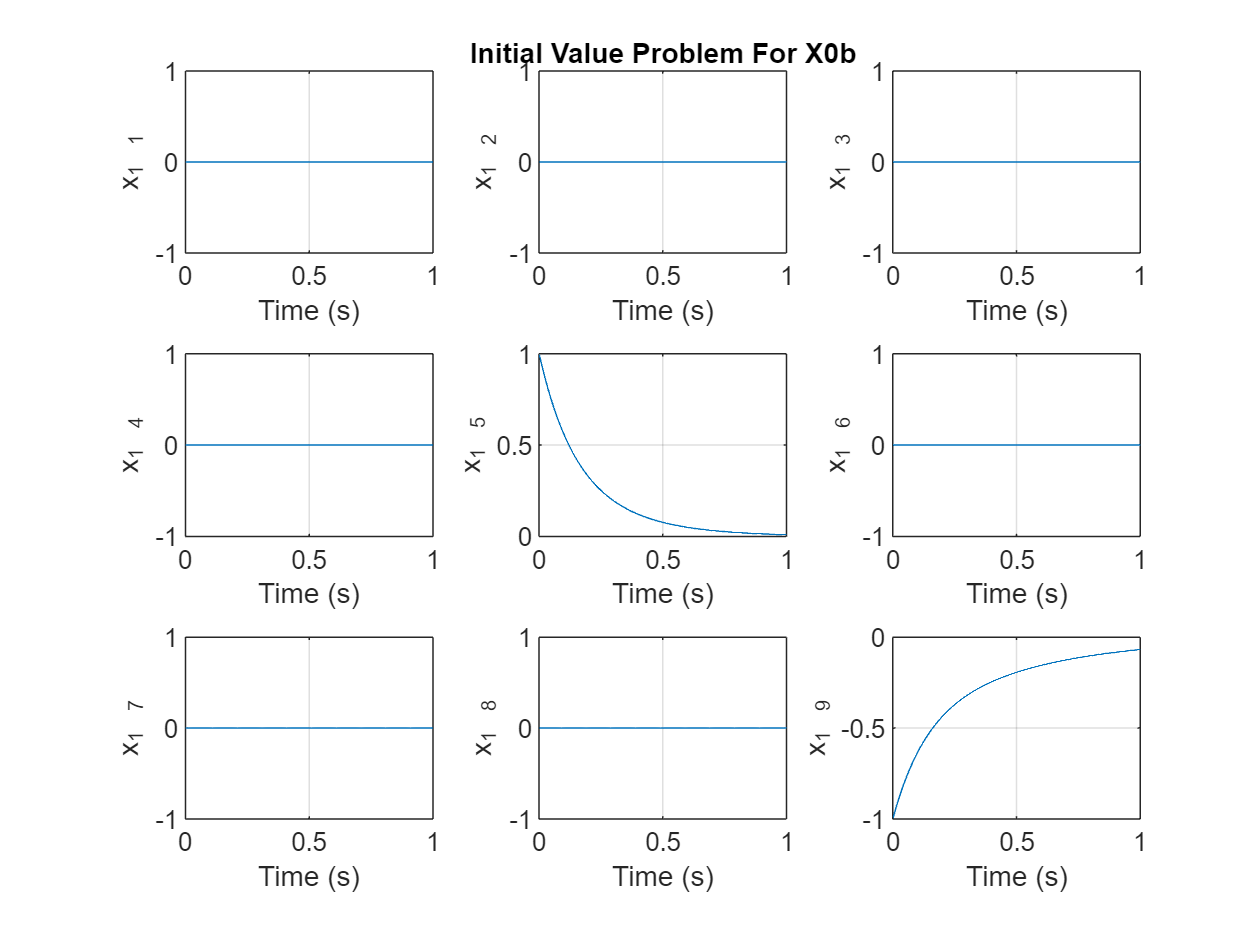

% --Compute IVR
    x_t = zeros(3,3,fs+1);
    for i = 1:3 
        x_t(i,i,:) = phi(i,i,:)*X0b(i);
    end

% --Plot solutions
    figure(2)
     for i = 1:3
        figure(2)
        subplot(3,3,1*i)
        x = squeeze(x_t(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 3)
        x = squeeze(x_t(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+3);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 6)
        x = squeeze(x_t(3,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+6);
            ylabel(label)
            xlabel('Time (s)')
            grid on
     end
     figure(2)
     subplot(3,3,2)
     title("Initial Value Problem For X0b")

c)  [2 pts]  Solve for the **initial value response** due the following initial conditions.

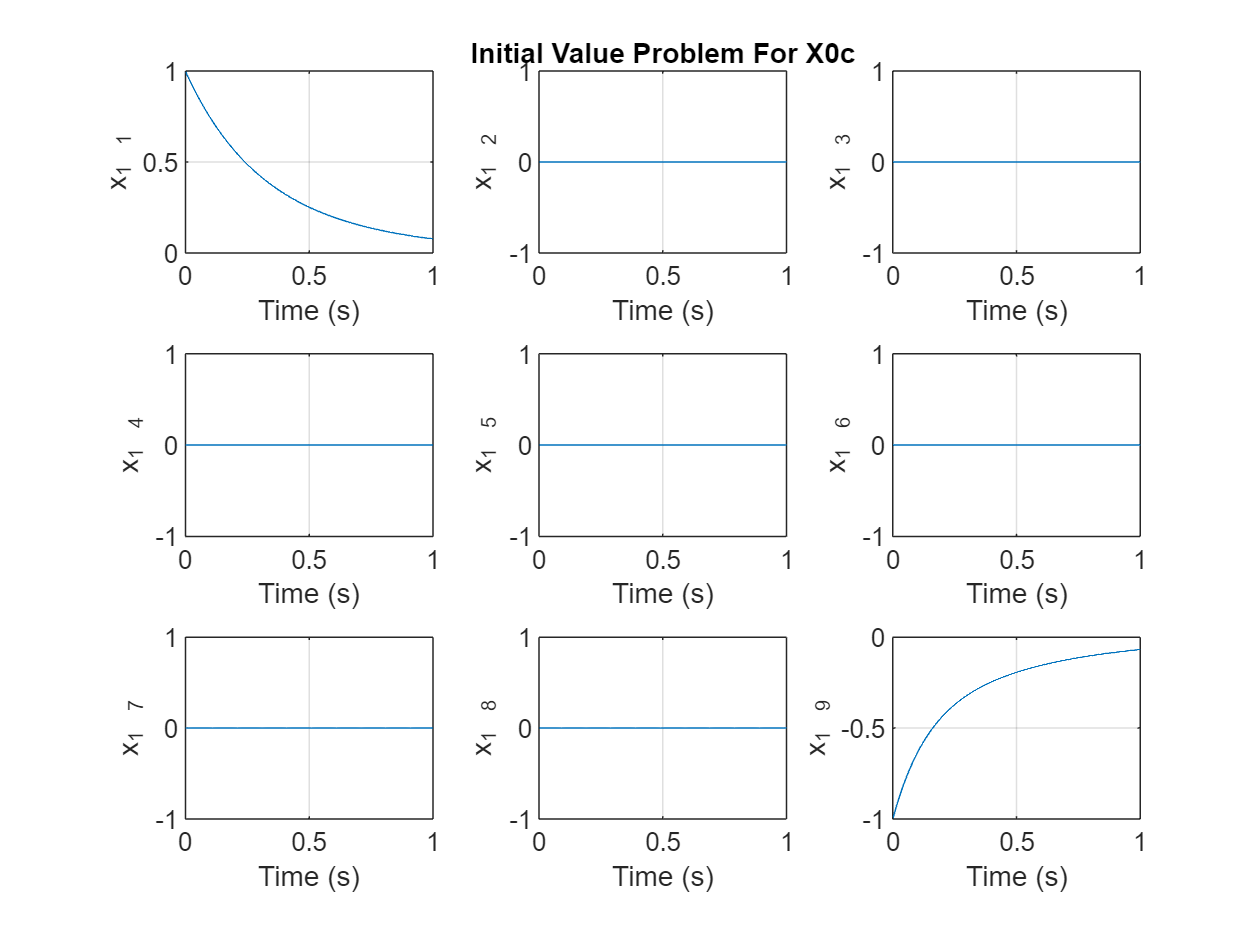

% --Problem statement
    X0c = [1; 0; -1];
% --Compute IVR
    x_t = zeros(3,3,fs+1);
    for i = 1:3 
        x_t(i,i,:) = phi(i,i,:)*X0c(i);
    end

% --Plot solutions
    figure(3)
     for i = 1:3
        figure(3)
        subplot(3,3,1*i)
        x = squeeze(x_t(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 3)
        x = squeeze(x_t(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+3);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 6)
        x = squeeze(x_t(3,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+6);
            ylabel(label)
            xlabel('Time (s)')
            grid on
     end
     figure(3)
     subplot(3,3,2)
     title("Initial Value Problem For X0c")

d)  [2 pts]  Solve for the **initial value response** due the following initial conditions.

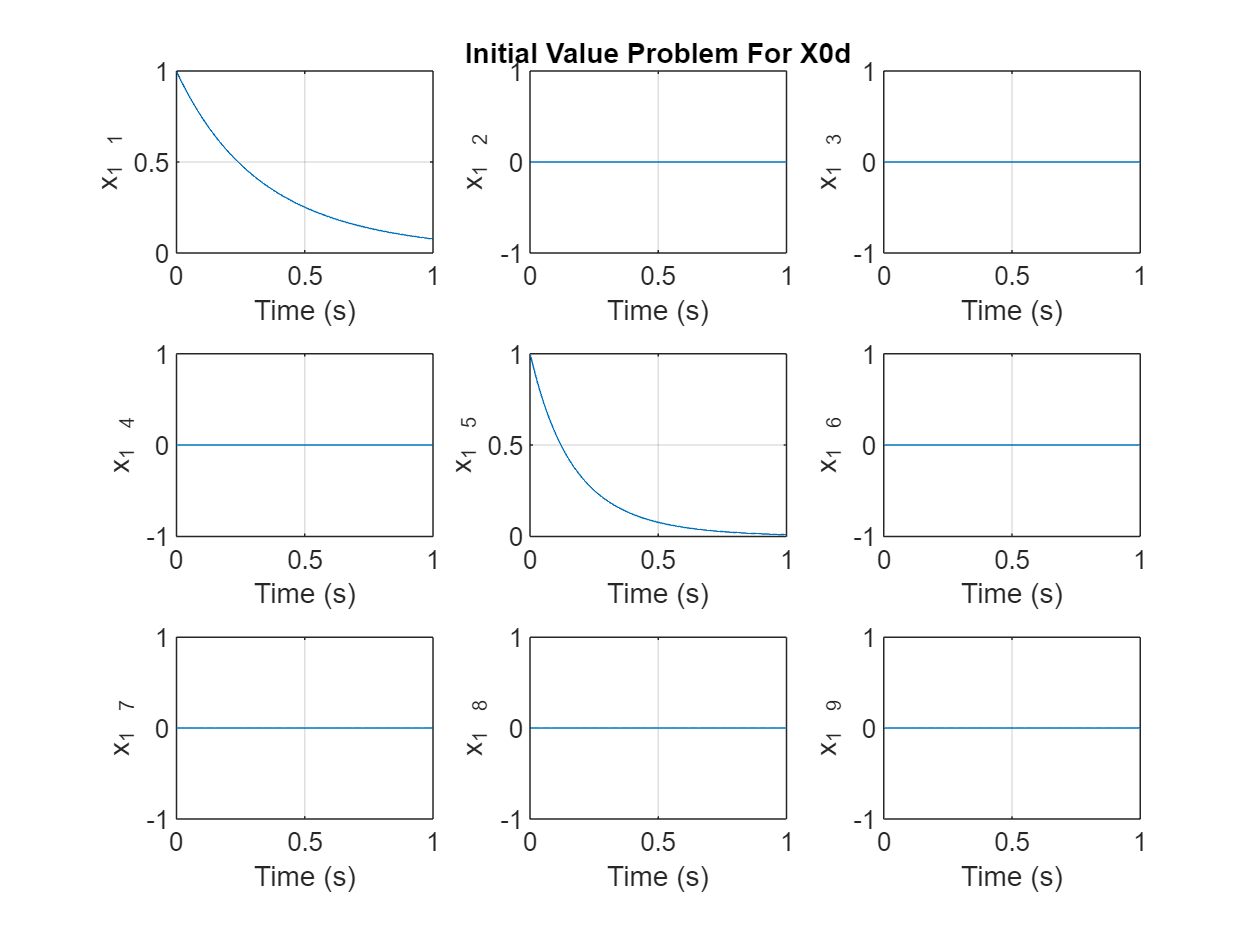

% --Problem Statement
     X0d = [1; 1; 0];

% --Compute IVR
    x_t = zeros(3,3,fs+1);
    for i = 1:3 
        x_t(i,i,:) = phi(i,i,:)*X0d(i);
    end

% --Plot solutions
    figure(5)
     for i = 1:3
        figure(4)
        subplot(3,3,1*i)
        x = squeeze(x_t(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 3)
        x = squeeze(x_t(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+3);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 6)
        x = squeeze(x_t(3,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("x_{1%3.0f}",i+6);
            ylabel(label)
            xlabel('Time (s)')
            grid on
     end
     figure(5)
     subplot(3,3,2)
     title("Initial Value Problem For X0d")

## Problem 3   [10 pts]

A homogeneous LTI dynamic system (i.e. there is no input to this system) has the following State Transition Matrix:


$$\Phi \left(t,t_0 \right)=\left\lbrack \begin{array}{cc}
\cos \left(\alpha \;\Delta t\right) & -\sin \left(\alpha \;\Delta t\right)\\
\sin \left(\alpha \;\Delta t\right) & \cos \left(\alpha \;\Delta t\right)
\end{array}\right\rbrack \;\;\;\;\textrm{where}\;\;\;\;\Delta t=t-t_0$$


You may use the Symbolic Toolbox.  You may use the Control System Toolbox.  You may use the LiveScript equation editor.  You may use basic Matlab functions.  You MUST show the steps and display all intermediate and final results.  If you have the correct answer, but do not show how you got that answer, points will be taken off.

a)  [5 pts]  Given an initial state:  $\mathbf{x}\left(t_0 \right)=\beta \left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$, **determine a future time** where the state trajectory $\mathbf{x}\left(t\right)$ returns to this initial state, i.e. $\mathbf{x}\left(t\right)=\mathbf{x}\left(t_0 \right)$.

% --Setup
    clear; clc; format compact; close all; 

% --Problem statement
    syms a b t
    phi = [cos(a*t) -sin(a*t);
           sin(a*t) cos(a*t)];
    xt0 = b*[1;1];

                Because we have sinusoidal inputs, our states will evolve sinusoidally, meaning that they will typically return at the same trajectory when we have a full cycle or one full period. This will happen when $T = \alpha2\pi$ radians.

% --Proving solution
    a = 1;
    t = 0;
    phi1 = subs(phi)

$$phi1 = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

    t = 2*pi;
    phi2 = subs(phi)

$$phi2 = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

    phi1 == phi2

$$ans = \left(\begin{array}{cc} 1=1 & 0=0\\ 0=0 & 1=1 \end{array}\right)$$

                Therefore, at each cycle the trajectories will evolve the same way.

b)  [5 pts]  Demonstrate your result by plotting the state trajectory over an appropriate time interval to capture the initial and final time.  You may assume any positive non-zero values for $\alpha$ and $\beta$.  Note that this is a numerical-only solution, i.e. no symbolic results should be used here.  Do NOT display any intermediate numerical calculations at each time step for the state trajectory!  That is what the plot is for.  Properly annotate your plot with xlabel, ylabel, grid, legend, and some indication of where the state trajectory returns to the initial state vector.

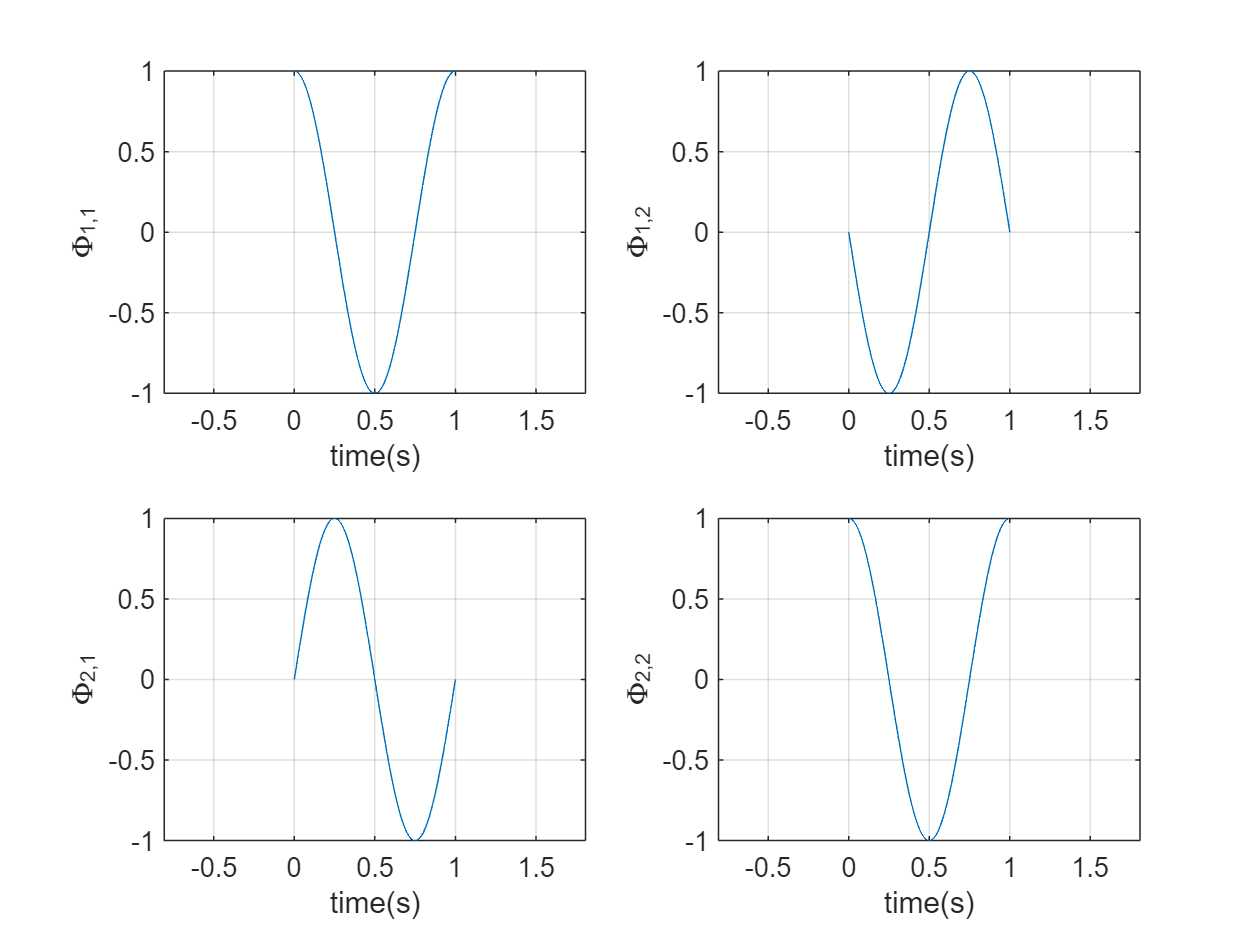

% --Plotting the trajectories
    a = 2*pi;
    b = 1;
    fs = 1000;
    maxt = 1;
    t = 0:1/fs:maxt;
    phi_1 = cos(a*t);
    phi_2 = -sin(a*t);
    phi_3 = sin(a*t);
    phi_4 = cos(a*t);

% --Plotting Matrix Exponential
    subplot(2,2,1)
    plot(t,phi_1)
        xlabel('time(s)')
        ylabel('\Phi_{1,1}')
        grid on
        axis equal

    subplot(2,2,2)
    plot(t,phi_2)
        xlabel('time(s)')
        ylabel('\Phi_{1,2}')
        grid on
        axis equal

    subplot(2,2,3)
    plot(t,phi_3)
        xlabel('time(s)')
        ylabel('\Phi_{2,1}')
        grid on
        axis equal

    subplot(2,2,4)
    plot(t,phi_4)
        xlabel('time(s)')
        ylabel('\Phi_{2,2}')
        grid on
        axis equal

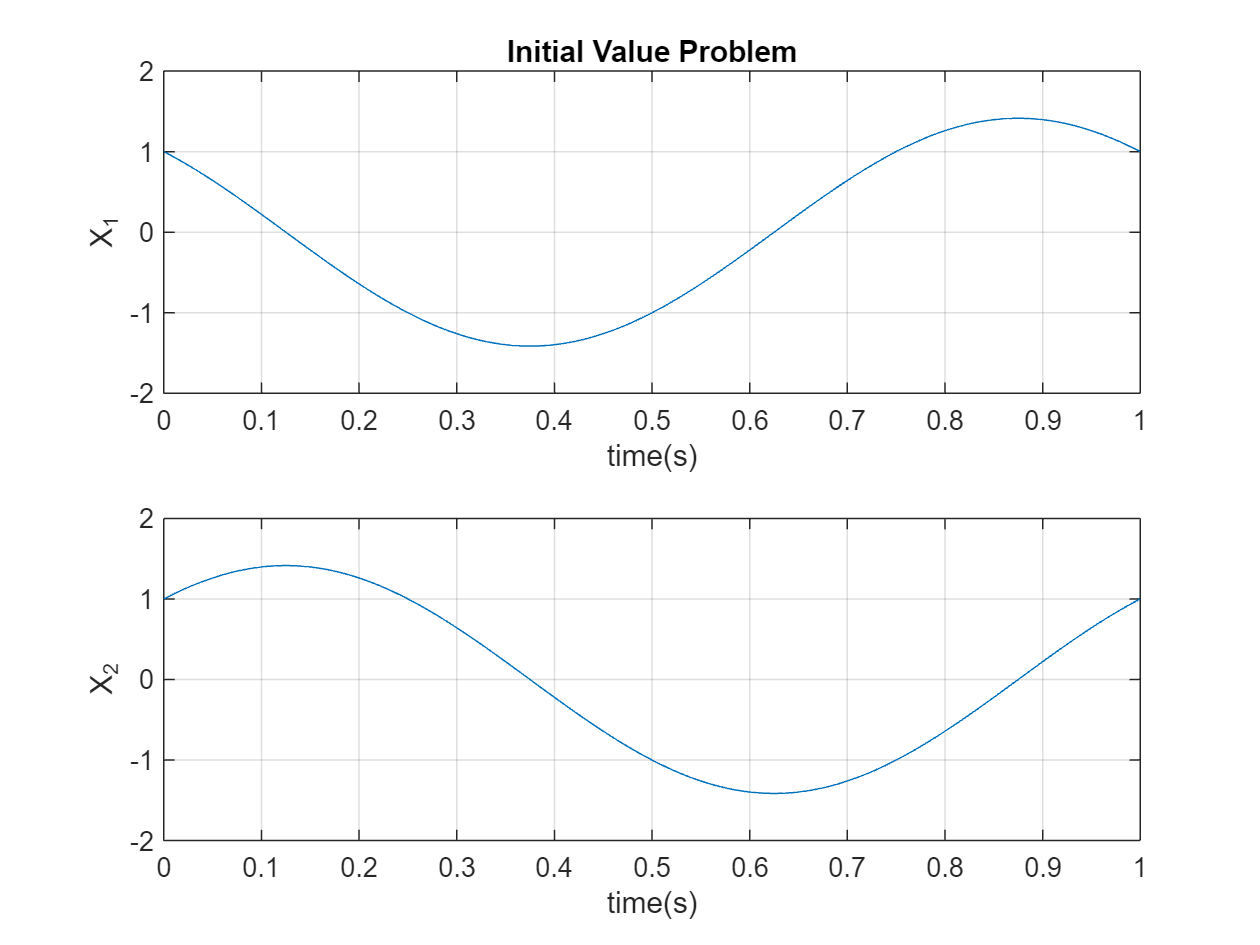

% --Finding IVT
    phi = [phi_1, phi_2;
            phi_3, phi_4];
    xt0 = [1;1];
    x = zeros(2,1,fs+1);
    x(1,1,:) = phi_1*xt0(1) + phi_2*xt0(2);
    x(2,1,:) = phi_3*xt0(1) + phi_4*xt0(2);

% --Plotting solutions
    figure()
    subplot(2,1,1)
    plot(t,x(1,:))
        xlabel('time(s)')
        ylabel('X_1')
        grid on
        title('Initial Value Problem')

    subplot(2,1,2)
    plot(t,x(2,:))
        xlabel('time(s)')
        ylabel('X_2')
        grid on

## Problem 4  [10 pts]

Given the following open-loop state equation:  $\dot{\mathbf{x}} =\mathbf{A}\;\mathbf{x}+\mathbf{B}\;u$, where:

% --setup
    clear; clc; format compact; close all;
       
% --Problem Setup
    A = [-1 0 20; 
        7 -2 7; 
        -20 0 -1];
    B = [0; -1; 2];
    G = [1,1,1];

You may use the Symbolic Toolbox.  You may **NOT** use any tools in the Control System Toolbox.  You may use the LiveScript equation editor.  You may use basic Matlab functions.  You MUST show the steps and display all intermediate and final results.  If you have the correct answer, but do not show how you got that answer, points will be taken off.

a)  [4 pts]  Determine a set of **desired closed-loop poles** that meet the following requirements:

- The 2% settling time associated with EACH closed-loop pole must be exactly 489 milliseconds

- The complex poles must have a 9.478% overshoot

% --Finding zeta such that meets overshoot
    PO = 9.478;
    t = 0.489;
    zeta = abs(log(PO/100)/(sqrt(pi^2 + log(PO/100)^2)))

zeta = 0.6000

    wn = 4/(t*zeta)

wn = 13.6333

                So our poles must be at the location of $\omega_n = 13.6333$ and $\zeta = 0.60$. So to turn this into a 3rd order system we can convert this to the following first order system times a second order system.

p1 = wn;
b = 2*zeta*wn

b = 16.3599

c = wn^2

c = 185.8657

denom = [1 b c];
poles = roots(denom)

poles =   -8.1800 +10.9066i
  -8.1800 -10.9066i


poles = [poles; p1];
CE = abs(poly(poles))

CE = 1.0e+03 *

    0.0010    0.0027    0.0372    2.5340


                So our set of poles that we can use are s = -13.6333, s = -8.1800 + 10.9i, and s = -8.18 - 10.9i

b)  [5 pts]  Determine numerical values for the **full state feedback gains** to place the poles at the desired locations from 4a.

% --Solve for G
    G = abs(inv([B, A*B, A^2 * B])*eye(3)*poles)'

G =    44.8449    0.5456    0.1118


c)  [1 pts]  **Verify that the gains** you obtained in 4b place the poles at the desired locations from 4a.

% --Verify answer is correct
    syms s
    Ac = vpa(det(s*eye(3) - [A - B*G]))

$$Ac = s^{3}+3.6780316888373081329888236723491\,s^{2}+2206.0117267033363842035887395173\,s+4331.6594191096771654058022081077$$

                This output shows the poles are close enough to warrant being in the correct locations for the proper response we desire. 

## **OPTIONAL Extra Credit   [3 pts]**

- **Do NOT attempt this problem until AFTER you have completed all problems above!**

- **This extra credit problem is NOT required!**

- **This extra credit will NOT enable your total exam grade to exceed 100%!**

Use the **Modal Expansion Theorem:**   $\mathbf{x}\left(t\right)=\sum_{n=1}^3 c_n {\mathbf{v}}_n e^{\lambda_n t}$, to derive the exact same results you obtained for the initial value responses in Problem 2b, 2c, and 2d.

You should only use the LiveScript equation editor, and/or basic Matlab functions.  You MUST show the steps and display all intermediate and final results.  If you have the correct answer, but do not show how you got that answer, points will be taken off.